# Script

## Setting-up

addpath(genpath('../functions'))
load coastlines

Default figure

set(0,'DefaultAxesBox','on')
% set(0,'defaultLineLineWidth',2)
% set(0,'DefaultFigureColormap',crameri('batlow'));
% colorder = [17, 138, 178;82, 43, 41; 204, 164, 59; 67, 100, 54; 228, 87, 46]/255;
% set(0,'defaultAxesColorOrder',colorder)
colorder = get(0,'defaultAxesColorOrder');colorder = repmat(colorder,10,1);

Read metadata

tblLog = readtable('../data/tracks/RawData.xlsx');
tblLog = tblLog(tblLog.Usable,:);
tblLog = tblLog(tblLog.multisensor,:);
%tblLog = tblLog(tblLog.StudyPressure,:);
%tblLog = tblLog(tblLog.StudyTraquet,:);
% tblLog = tblLog(tblLog.StudyKenya,:);
tblLog = tblLog(tblLog.StudyStarling,:);
tblLog

tblLog = 1×37 table
    Usable     GDL_ID      multisensor         LatinName               CommonName          mass    wingSpan      DataFileName       TwilightShiftK    UTC_Attached    LongitudeAttached    LatitudeAttached    UTC_Removed    LongitudeRemoved    LatitudeRemoved    DEMAttached    UTC_FirstData    UTC_LastData    SubsetStart     SubsetEnd     CalibFirstStart    CalibFirstEnd    CalibSecondStart    CalibSecondEnd    bndy_N    bndy_S    bndy_W    bndy_E      Color       StudyPressur

Select geolocator

lt=1;

Read data

rawlt = importPAM(['../data/tracks/' tblLog.DataFileName{lt}], tblLog.SubsetStart(lt), tblLog.SubsetEnd(lt));

if any(rawlt.light.obs<0)
    warning('Removing negative light value')
    rawlt.light.obs(rawlt.light.obs<0) = nan;
end
rawlt.light.obstrans = log(double(rawlt.light.obs)+0.0001) + abs(min(log(double(rawlt.light.obs)+0.0001)));

Add calibration period

rawlt.calib.first_period = [tblLog.CalibFirstStart(lt) tblLog.CalibFirstEnd(lt)];
rawlt.calib.second_period = [tblLog.CalibSecondStart(lt) tblLog.CalibSecondEnd(lt)];
rawlt.calib.lon = tblLog.LongitudeAttached(lt); % Inverted in the spreadsheet
rawlt.calib.lat = tblLog.LatitudeAttached(lt);
tblLog(lt,:)

ans = 1×37 table
    Usable     GDL_ID      multisensor         LatinName               CommonName          mass    wingSpan      DataFileName       TwilightShiftK    UTC_Attached    LongitudeAttached    LatitudeAttached    UTC_Removed    LongitudeRemoved    LatitudeRemoved    DEMAttached    UTC_FirstData    UTC_LastData    SubsetStart     SubsetEnd     CalibFirstStart    CalibFirstEnd    CalibSecondStart    CalibSecondEnd    bndy_N    bndy_S    bndy_W    bndy_E      Color       StudyPressure</

### Check Subset and calibration

Visualize basic data

% figure('position',[0 0 1200 1000]); clear ax
% % ax(1)=subplot(4,1,1);
% % plot(raw.light.date,raw.light.obs)
% % ylabel('light')
% ax(2)=subplot(4,1,2); hold on;
% fill([raw.calib.first_period fliplr(raw.calib.first_period)],[min(raw.pressure.obs) min(raw.pressure.obs) max(raw.pressure.obs) max(raw.pressure.obs)],'r','FaceAlpha',0.2,'EdgeAlpha',0)
% fill([raw.calib.second_period fliplr(raw.calib.second_period)],[min(raw.pressure.obs) min(raw.pressure.obs) max(raw.pressure.obs) max(raw.pressure.obs)],'r','FaceAlpha',0.2,'EdgeAlpha',0)
% plot(raw.pressure.date,raw.pressure.obs)
% ylabel('pressure')
% ax(3)=subplot(4,1,3); hold on;
% %plot(raw.acceleration.date,raw.acceleration.pit)
% plot(raw.acceleration.date,raw.acceleration.act)
% ylabel('acceleration')
% % ax(4)=subplot(4,1,4);
% % plot(raw.temperature.date,raw.temperature.obs)
% % ylabel('temperature')
% linkaxes(ax,'x'); axis tight
% ax(5)=subplot(5,1,5); hold on;
% plot(raw.magnetic.date,raw.magnetic.gX)
% plot(raw.magnetic.date,raw.magnetic.gY)
% plot(raw.magnetic.date,raw.magnetic.gZ)
% plot(raw.magnetic.date,raw.magnetic.mX)
% plot(raw.magnetic.date,raw.magnetic.mY)
% plot(raw.magnetic.date,raw.magnetic.mZ)
% ylabel('magnetic')
% linkaxes(ax,'x'); axis tight

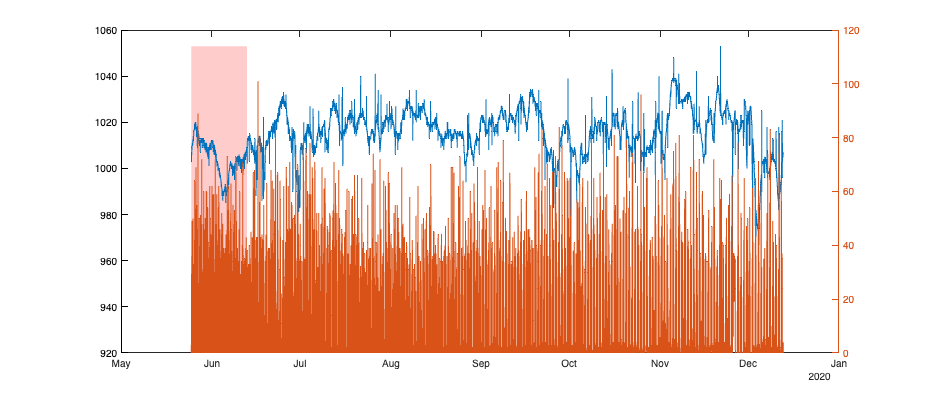

figure('position',[0 0 1400 600]); hold on;
if ~any(isnat(rawlt.calib.first_period))
    fill([rawlt.calib.first_period fliplr(rawlt.calib.first_period)],[min(rawlt.pressure.obs) min(rawlt.pressure.obs) max(rawlt.pressure.obs) max(rawlt.pressure.obs)],'r','FaceAlpha',0.2,'EdgeAlpha',0)
    fill([rawlt.calib.second_period fliplr(rawlt.calib.second_period)],[min(rawlt.pressure.obs) min(rawlt.pressure.obs) max(rawlt.pressure.obs) max(rawlt.pressure.obs)],'r','FaceAlpha',0.2,'EdgeAlpha',0)
end
plot(rawlt.pressure.date,rawlt.pressure.obs)
yyaxis 'right'
plot(rawlt.acceleration.date,rawlt.acceleration.act)

ImagePlot

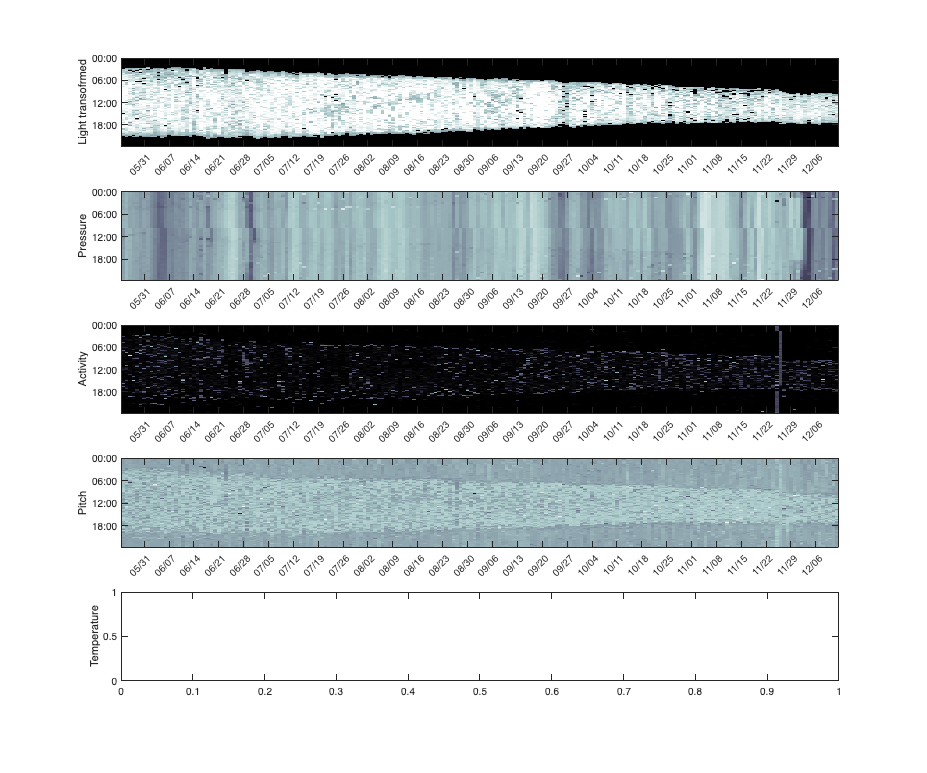

figure('position',[0 0 1200 1000]);
ax=subplot(5,1,1); sensorIMG(ax,rawlt.light.date,rawlt.light.obstrans,tblLog.TwilightShiftK(lt)); ylabel('Light transofrmed')
ax=subplot(5,1,2); sensorIMG(ax,rawlt.pressure.date,rawlt.pressure.obs,tblLog.TwilightShiftK(lt)); ylabel('Pressure')
ax=subplot(5,1,3); sensorIMG(ax,rawlt.acceleration.date,rawlt.acceleration.act,tblLog.TwilightShiftK(lt)); ylabel('Activity')
ax=subplot(5,1,4); sensorIMG(ax,rawlt.acceleration.date,rawlt.acceleration.pit,tblLog.TwilightShiftK(lt)); ylabel('Pitch')
ax=subplot(5,1,5); sensorIMG(ax,rawlt.temperature.date,rawlt.temperature.obs,tblLog.TwilightShiftK(lt)); ylabel('Temperature')

## Twilight Annotation

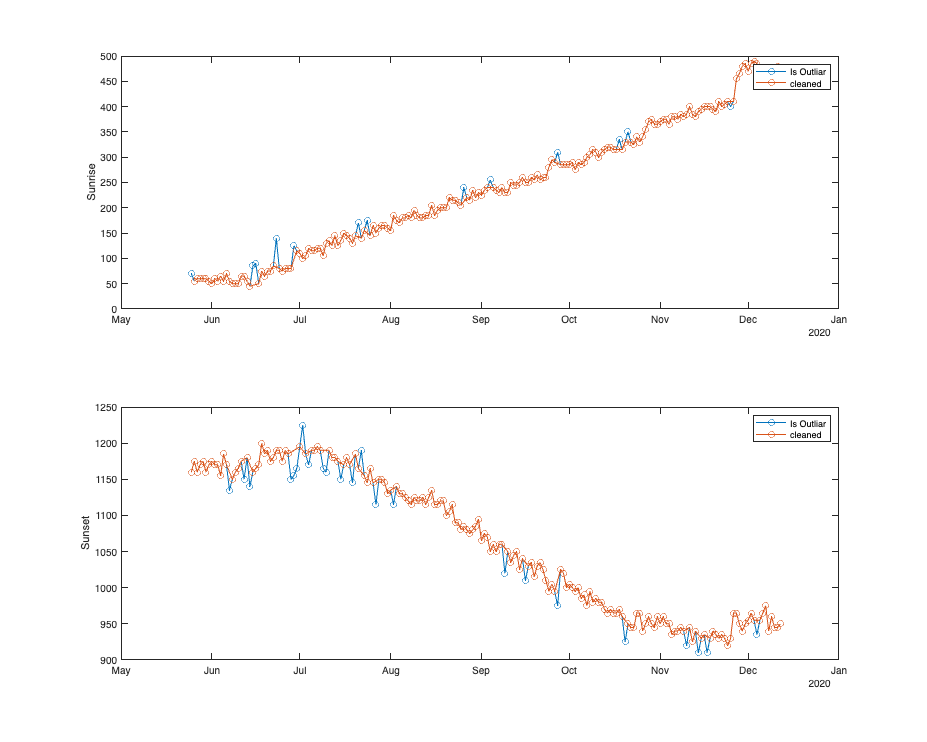

twllt = twilightEdit(findTwilightsRaf(rawlt.light,[],tblLog.TwilightShiftK(lt)),false);
twllt = twilightEditTrainset(rawlt,twllt);

Illustration

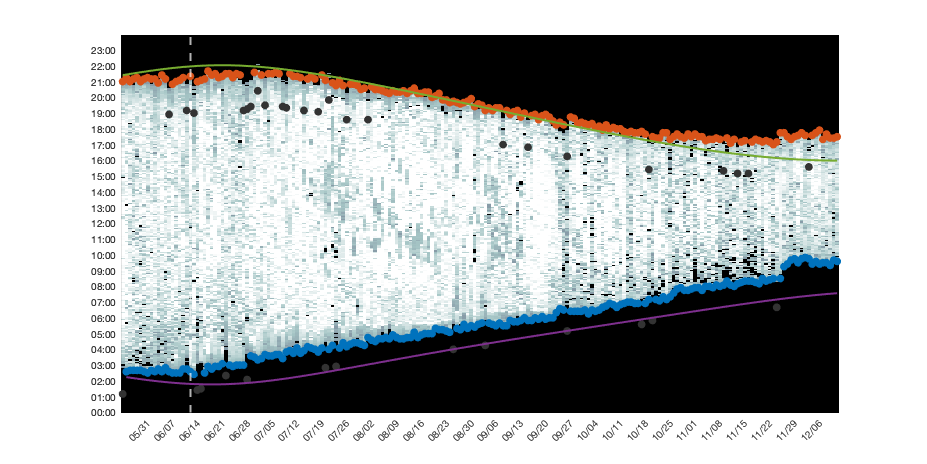

figure('position',[0 0 1200 600]); hold on; 
sensorIMG(gca,rawlt.light.date,rawlt.light.obstrans,tblLog.TwilightShiftK(lt),twllt,rawlt.calib); 

## Calibration

Compute the date_id of calibration

id_calib = rawlt.calib.first_period(1)<twllt.Twilight&twllt.Twilight<rawlt.calib.first_period(2) | rawlt.calib.second_period(1)<twllt.Twilight&twllt.Twilight<rawlt.calib.second_period(2);

And compute the calibration

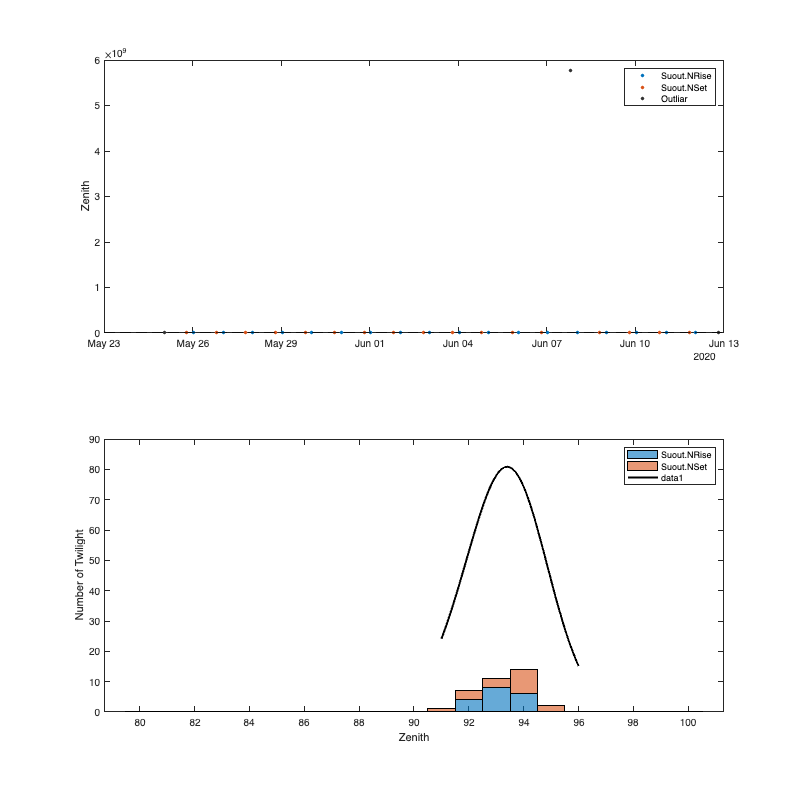

gElt = getElevation(twllt(id_calib,:),[rawlt.calib.lon rawlt.calib.lat],true,80:100);
bd=1.2;
xi = floor(min(gElt.z(~twllt.isOutliar(id_calib)))):0.01:ceil(max(gElt.z(~twllt.isOutliar(id_calib))));
[gElt.f,gElt.xi]=ksdensity(gElt.z(~twllt.isOutliar(id_calib)),xi,'Bandwidth',bd);
gElt.pdf = @(x) interp1(gElt.xi,gElt.f,x,'nearest','extrap');
plot(xi,gElt.pdf(xi)*300,'-k','LineWidth',2)

### Compute coordinate

Without using the calibration (default is 96°)

crds_wo = coord(twllt(id_calib,:));
crds_wo.lat(crds_wo.lat>90)=crds_wo.lat(crds_wo.lat>90)-90;
crds_wo.lat(crds_wo.lat<-90)=crds_wo.lat(crds_wo.lat<-90)+90;

Normal Calibration using the median

crds_wm = coord(twllt(id_calib,:), gElt.medZ);
crds_wm2 = coord(twllt(id_calib,:), gElt.z);

Figure

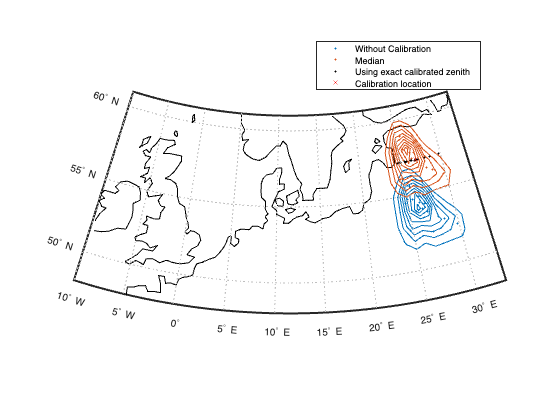

dl=1;
if tblLog.bndy_N(lt)>0
    glat = tblLog.bndy_S(lt):tblLog.bndy_N(lt);
    glon = tblLog.bndy_W(lt):tblLog.bndy_E(lt);
else
    glat = (min(crds_wo.lat)-dl):(max(crds_wo.lat)+dl);
    glon = (min(crds_wo.lon)-dl):(max(crds_wo.lon)+dl);
end
[gLON,gLAT]=meshgrid(glon,glat);
figure; worldmap([min(glat) max(glat)], [min(glon) max(glon)]);  hold on; h=[];
% surfm(reshape(xi(:,2),n,n),reshape(xi(:,1),n,n),); colormap(flipud(bone))
plotm(coastlat,coastlon,'k');
contourm(gLAT,gLON,reshape(ksdensity([crds_wo.lon(~crds_wo.isOutliar), crds_wo.lat(~crds_wo.isOutliar)],[gLON(:),gLAT(:)]),size(gLAT)),'color',colorder(1,:))
h(1)=plotm(crds_wo.lat(~crds_wo.isOutliar),crds_wo.lon(~crds_wo.isOutliar),'.','color',colorder(1,:));
contourm(gLAT,gLON,reshape(ksdensity([crds_wm.lon(~crds_wm.isOutliar), crds_wm.lat(~crds_wm.isOutliar)],[gLON(:),gLAT(:)]),size(gLAT)),'color',colorder(2,:))
h(2)=plotm(crds_wm.lat(~crds_wm.isOutliar),crds_wm.lon(~crds_wm.isOutliar),'.','color',colorder(2,:));
h(3)=plotm(crds_wm2.lat(~crds_wm2.isOutliar),crds_wm2.lon(~crds_wm2.isOutliar),'.k');
h(4)=plotm(rawlt.calib.lat,rawlt.calib.lon,'xr');
legend(h,'Without Calibration','Median','Using exact calibrated zenith','Calibration location','location','best')

## Activity Analysis

First, we use activity data (and pressure data) to group activities together and build a stationary table summurizing the periods at fixed location and the period of migration. 

Add if isDay to improve the classification

rawlt.acceleration.isDay = zeros(size(rawlt.acceleration.date));%isDay(raw.acceleration.date,twl);

Automatic classify based on activity

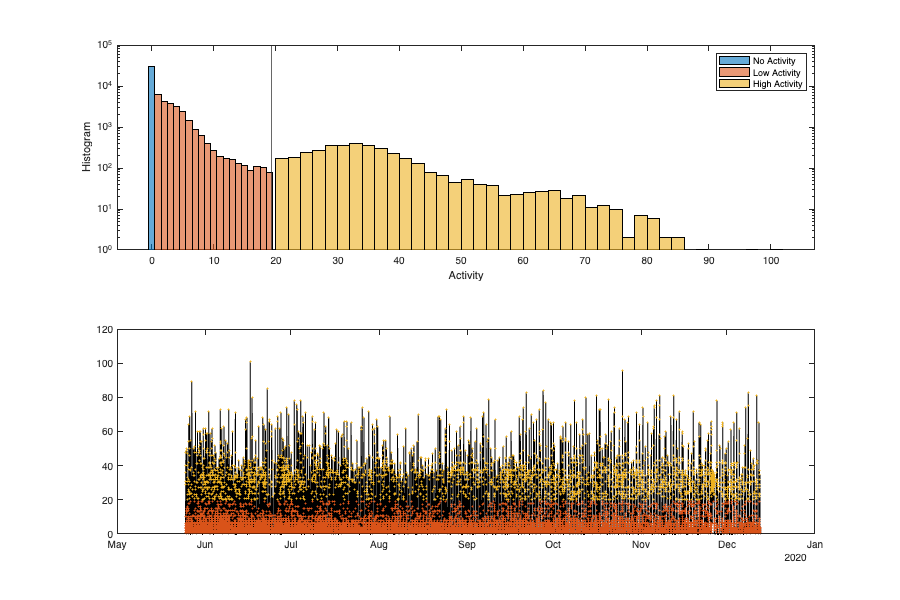

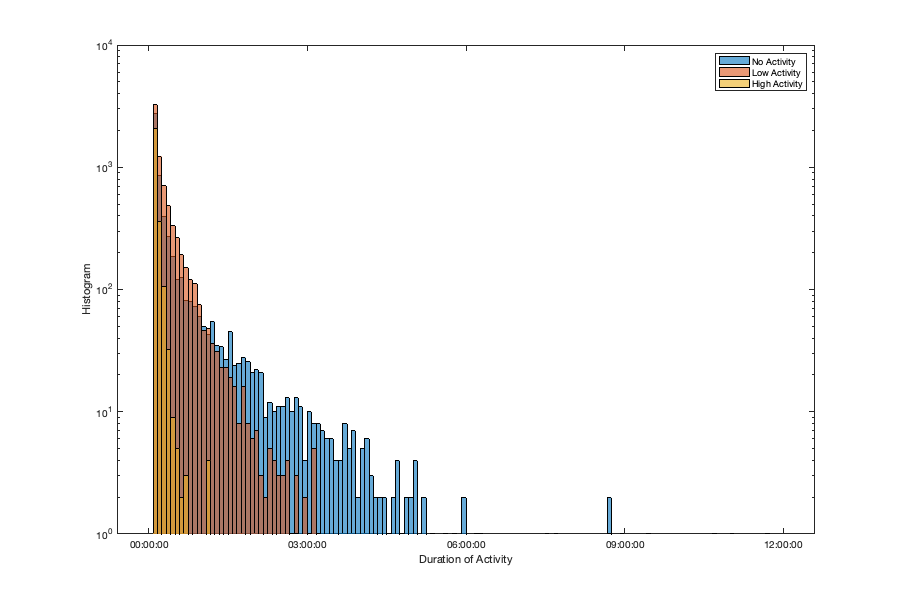

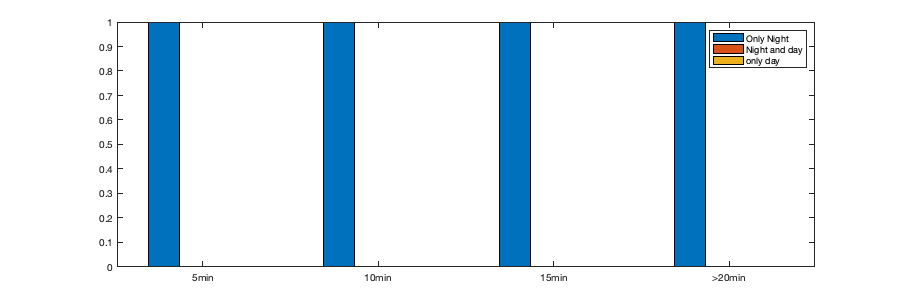

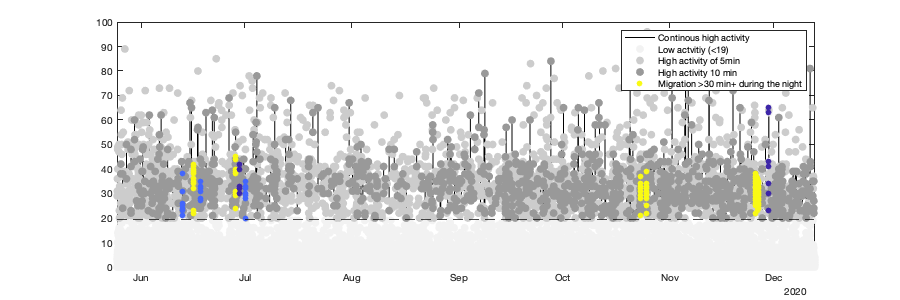

[~,km] = classifyActivityRaf(rawlt.acceleration,'auto',duration(0,30,0),true);

Because the automatic classification is not really good, we performed an additional manual editing

activity = classifyActivityTrainsetRaf(rawlt,km);

Build the table of migration only activities

activityMiglt = activity(activity.km==3,:);

If the geolocator does not measure activity, we can still classify activity with pressure

if isnat(rawlt.acceleration.date)
    activity = classifyActivityTrainsetRaf(rawlt,0);
    activityMiglt = activity(activity.km==3,:);
end

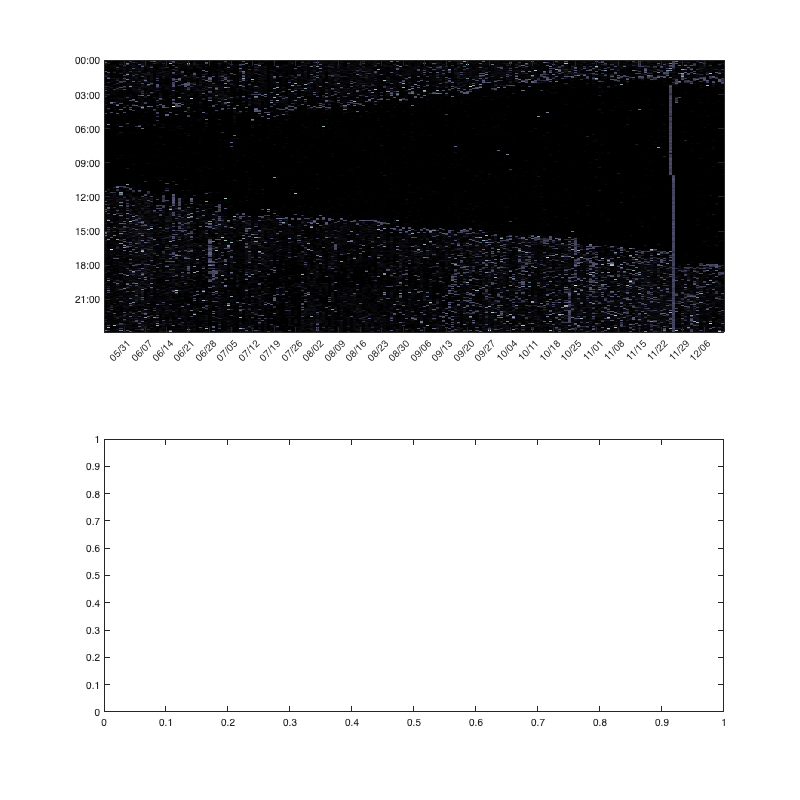

Unrecognized function or variable 'activityMiglt'.

figure('position',[0 0 1200 1200]); 
subplot(2,1,1); sensorIMG(gca,rawlt.acceleration.date,rawlt.acceleration.act,tblLog.TwilightShiftK(lt)+.5);
subplot(2,1,2); activityIMG(gca,rawlt.acceleration.date,activityMiglt,tblLog.TwilightShiftK(lt)+.5);

% figure('position',[0 0 1000 400]);  hold on
% plot(raw.pressure.date,raw.pressure.obs,'k')
% for i_s = 1:height(activityMig)
%     id_tgr = activityMig.date_min(i_s)<=raw.pressure.date & raw.pressure.date <= activityMig.date_max(i_s);
%     plot(raw.pressure.date(id_tgr), raw.pressure.obs(id_tgr),'LineWidth',2)
% end
% yyaxis 'right'
% plot(raw.acceleration.date,raw.acceleration.act)
% ylabel('acceleration')
% axis tight

## Group Twilight

Combine twlight based on activity

% Stationary period
% Group twilights and activityMig into a single stationary table
% create table
stalt = table();
% Create start and stop
stalt.start = [tblLog.SubsetStart(lt);activityMiglt.date_max];
stalt.end = [activityMiglt.date_min;tblLog.SubsetEnd(lt)];
% Delete stationary period too short
% sort(sta.end-sta.start)
% stalt(hours(stalt.end-stalt.start)<7,:)=[];
% sta.id = (1:height(sta))';

for i_s=1:height(stalt)
    % Find and match activity activity
    if i_s~=height(stalt)
        idAct = stalt.end(i_s) <= activityMiglt.date_min &  activityMiglt.date_max <= stalt.start(i_s+1);
        stalt.actNb(i_s) = sum(idAct);
        stalt.actSum(i_s) = sum(activityMiglt.act_sum(idAct));
        stalt.actDuration(i_s) = sum(activityMiglt.duration(idAct));
        activityMiglt.staID(idAct)=i_s;
    end
    
    % Find and match twilight
    idTwl = stalt.start(i_s) <= twllt.Twilight & twllt.Twilight <= stalt.end(i_s);
    stalt.twlNb(i_s) = sum(idTwl);
    twllt.staID(idTwl) = i_s;
end
stalt.staID = (1:height(stalt))';

Compute the effort of flight by normalizing the flight duration by activity intensity

if any(isnan(stalt.actSum))
    stalt.actEffort =  stalt.actDuration;
    warning(['Cannot compute effort of flight for' rawlt.GDL_ID])
else
    stalt.actEffort =  stalt.actSum./sum(stalt.actSum)*sum(stalt.actDuration);
end 

 Label stationary period & Migration

stalt.status=repmat("",height(stalt),1);
[~,id]=maxk(stalt.twlNb,3);
if tblLog.GDL_ID{lt}=="24FF"
    iws=id(2);
elseif tblLog.GDL_ID{lt}=="20OA"
    iws=id(2);
else
    iws = id(1);
end
    
stalt.status(iws)='wintering';
stalt.status(1:height(stalt)<iws)='migration_post_equipement';
stalt.status(1:height(stalt)>iws)='migration_pre_retrival';
stalt.status(1)='equipment';
if ~isnat(tblLog.CalibSecondStart(lt))
    stalt.status(end)='retrieval';
end

### Check stationary Period

Downscale to 1hr

dt = 1./hours(diff(rawlt.pressure.date(1:2)));
pres_g = movmedian(rawlt.pressure.obs,3);
pres_g = pres_g(1:dt:end);
gtime = rawlt.pressure.date(1:dt:end);

See on figure

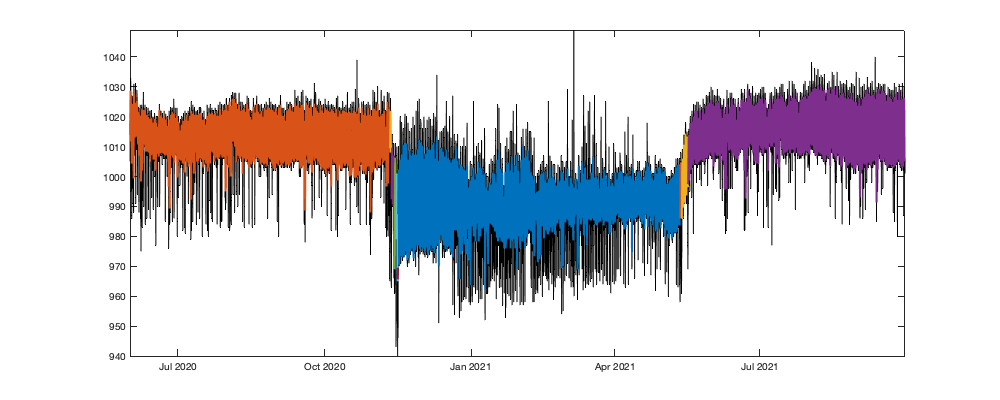

figure('position',[0 0 1000 400]);  hold on
plot(rawlt.pressure.date,rawlt.pressure.obs,'k')
for i_s = 1:height(stalt)
    id_tgr = stalt.start(i_s) < gtime & gtime < stalt.end(i_s);
    pres_g_tgr = movmean(pres_g(id_tgr),3);
    plot(gtime(id_tgr), pres_g_tgr,'LineWidth',2)
end
% yyaxis 'right'
% plot(rawlt.acceleration.date,rawlt.acceleration.act)
% ylabel('acceleration')
axis tight

## Coordinates for long stationary period

q = [.1 .2 .5 .8 .9];
crds_lat = nan(height(stalt),numel(q)); 
crds_lon = nan(height(stalt),numel(q));

for i_g = 1:height(stalt)
    crds_tmp = coord(twllt(twllt.staID==i_g,:), gElt.medZ);
    crds_lat(i_g,:) = quantile(crds_tmp.lat(~crds_tmp.isOutliar),q);
    crds_lon(i_g,:) = quantile(crds_tmp.lon(~crds_tmp.isOutliar),q);
end

Filter to keep only group with at least 10 twilihgts

grp_id = find(stalt.twlNb>=10);

Figure

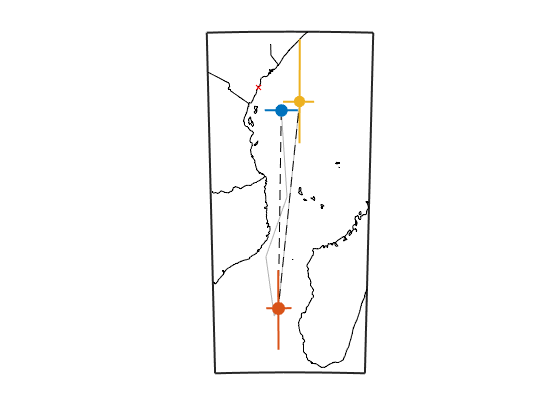

figure; col = get(gca,'colororder'); dl=5;
h = worldmap([floor(min(crds_lat(grp_id,3)))-dl ceil(max(crds_lat(grp_id,3)))+dl],[floor(min(crds_lon(grp_id,3)))-dl ceil(max(crds_lon(grp_id,3)))+dl]); hold on;
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
% surfm(reshape(xi(:,2),n,n),reshape(xi(:,1),n,n),); colormap(flipud(bone))
bordersm('countries','k');
plotm(rawlt.calib.lat,rawlt.calib.lon,'xr')
id=~any(isnan(crds_lon)&isnan(crds_lat),2);
plotm(crds_lat(id,3),crds_lon(id,3),'-','color',[.7 .7 .7])
plotm(crds_lat(grp_id,3),crds_lon(grp_id,3),'--k')
for i_g = 1:numel(grp_id)
    plotm(crds_lat(grp_id(i_g),[2 4]),crds_lon(grp_id(i_g),[3 3]),'Color',colorder(i_g,:),'linewidth', 2)
    plotm(crds_lat(grp_id(i_g),[3 3]),crds_lon(grp_id(i_g),[2 4]),'Color',colorder(i_g,:),'linewidth', 2)
    scatterm(crds_lat(grp_id(i_g),3),crds_lon(grp_id(i_g),3),stalt.twlNb(grp_id(i_g))/2,colorder(i_g,:),'o','filled')    
end

### Twilight Visualiztation

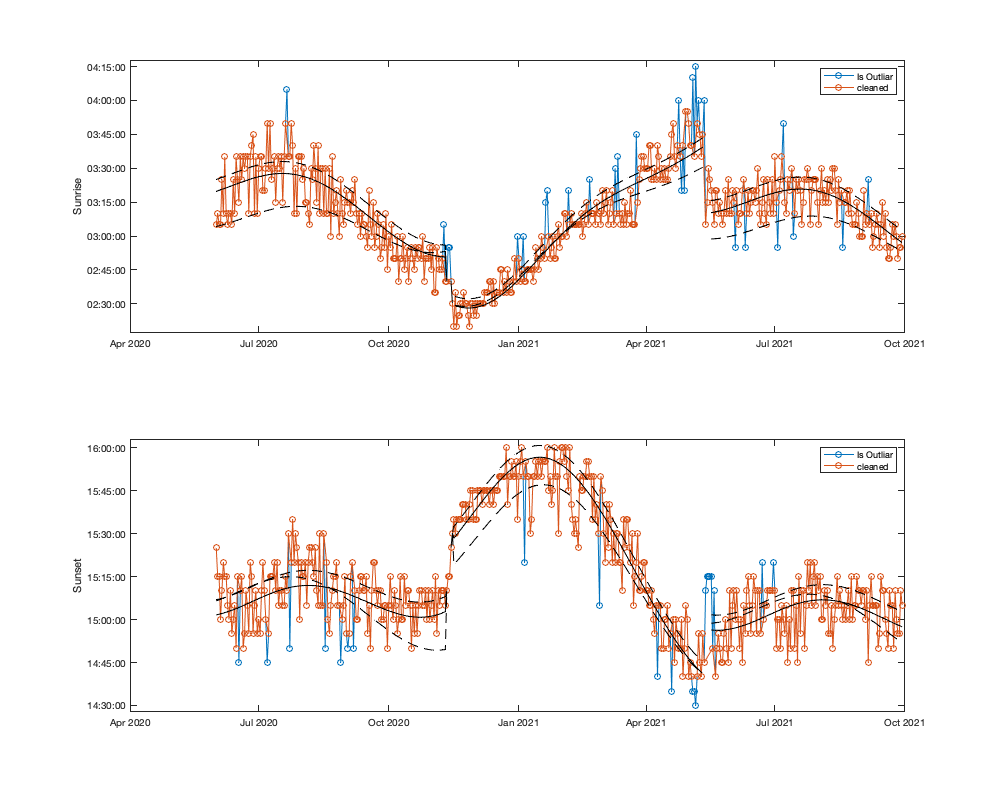

twlight_theo = NaT(height(twllt),5);
for i_s=1:height(stalt)
    id = twllt.staID==i_s;
    twlight_theo(id,1) = twilight(twllt.Twilight(id), crds_lon(i_s,1), crds_lat(i_s,1), twllt.Rise(id), gElt.medZ);
    twlight_theo(id,2) = twilight(twllt.Twilight(id), crds_lon(i_s,2), crds_lat(i_s,3), twllt.Rise(id), gElt.medZ);
    twlight_theo(id,3) = twilight(twllt.Twilight(id), crds_lon(i_s,3), crds_lat(i_s,3), twllt.Rise(id), gElt.medZ);
    twlight_theo(id,4) = twilight(twllt.Twilight(id), crds_lon(i_s,4), crds_lat(i_s,4), twllt.Rise(id), gElt.medZ);
    twlight_theo(id,5) = twilight(twllt.Twilight(id), crds_lon(i_s,5), crds_lat(i_s,5), twllt.Rise(id), gElt.medZ);
end

twl_day = dateshift(twllt.Twilight,'start','day');
twl_hour = twllt.Twilight-twl_day;
twl_hour_theo = twlight_theo-twl_day;

figure('position',[0 0 1000 800]);
subplot(2,1,1); hold on; ylabel('Sunrise'); box on;
plot(twl_day(twllt.Rise), twl_hour(twllt.Rise),'-o')
plot(twl_day(twllt.Rise & ~twllt.isOutliar), twl_hour(twllt.Rise & ~twllt.isOutliar),'-o')
plot(twl_day(twllt.Rise), twl_hour_theo(twllt.Rise,3),'-k')
plot(twl_day(twllt.Rise), twl_hour_theo(twllt.Rise,4),'--k')
plot(twl_day(twllt.Rise), twl_hour_theo(twllt.Rise,2),'--k')
legend('Is Outliar', 'cleaned');
subplot(2,1,2); hold on; ylabel('Sunset'); box on;
plot(twl_day(~twllt.Rise), twl_hour(~twllt.Rise),'-o')
plot(twl_day(~twllt.Rise & ~twllt.isOutliar), twl_hour(~twllt.Rise & ~twllt.isOutliar),'-o')
plot(twl_day(~twllt.Rise), twl_hour_theo(~twllt.Rise,3),'-k')
plot(twl_day(~twllt.Rise), twl_hour_theo(~twllt.Rise,2),'--k')
plot(twl_day(~twllt.Rise), twl_hour_theo(~twllt.Rise,4),'--k')
legend('Is Outliar', 'cleaned');

## Compute location based on prob map

dl=5;
lat_t = floor(min(crds_lat(:,3))-dl):.25:ceil(max(crds_lat(:,3))+dl);
lat_t = lat_t(lat_t>-90 & lat_t<90);
lon_t = floor(min(crds_lon(:,3))-dl):.25:ceil(max(crds_lon(:,3))+dl);

[LON, LAT] = meshgrid(lon_t,lat_t);

Compute the probability map for each twilight

coordProb = coordMapProb(twllt, gElt, lon_t, lat_t);

Combine the map per stationary period

% w=0.1;
alpha=0.1;
light_problt = nan(numel(lat_t),numel(lon_t),height(stalt));
for i_g = 1:height(stalt)
    id_g = twllt.staID==i_g&~twllt.isOutliar;
    w = alpha + (1-alpha)*1/sum(id_g);
    light_problt(:,:,i_g) = exp(w*sum(log(coordProb(:,:,id_g)),3));
end

Mask water

tmp = find(isnan(coastlat));
mask_water=true(size(LAT));
for id=1:numel(tmp)-1
    mask_water(inpolygon(LAT,LON,coastlat(tmp(id):tmp(id+1)),coastlon(tmp(id):tmp(id+1))))=false;
end
light_problt(repmat(mask_water,1,1,height(stalt)))=0;

Normalize

% coordProbSta_r./sum(coordProbSta_r)

stalt(stalt.twlNb>10,:)

ans = 6×8 table
           start                    end             actNb    actSum    actDuration    twlNb    staID    actEffort
    ____________________    ____________________    _____    ______    ___________    _____    _____    _________

    20-Jun-2017 00:00:00    21-Jul-2017 20:10:00      1       2407      05:55:00        64       1      05:55:00 
    22-Jul-2017 01:55:00    28-Jul-2017 19:50:00      1       2838      06:55:00        14       2      06:55:00 
    31-Jul-2017 00:00:00    16-Aug-2017 18:40:00      1       8248      17:25:00        34       5      17:25:00 
    30-Aug-2017 23:10:00    06-Nov-2017 18:25:00      1       3217      08:05:00       136      14      08:05:00 
    09-Nov-2017 19:40:00   

i_g=5;
stalt(i_g,:)

ans = 1×8 table
       start               end             actNb    actSum    actDuration    twlNb    staID    actEffort
    ___________    ____________________    _____    ______    ___________    _____    _____    _________

    31-Jul-2017    16-Aug-2017 18:40:00      1       8248      17:25:00       34        5      17:25:00 


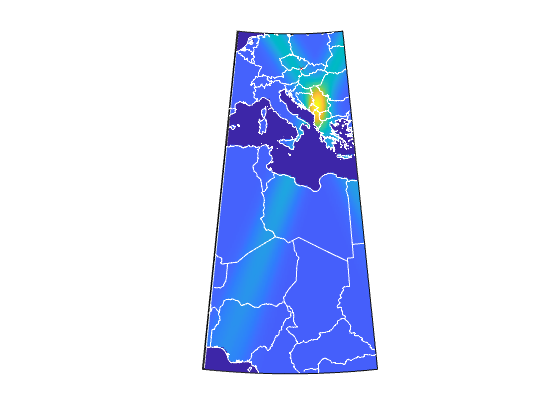

figure; h=worldmap([min(lat_t) max(lat_t)],[min(lon_t) max(lon_t)]);  hold on;
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(LAT,LON,light_problt(:,:,i_g))
bordersm('countries','w');
plotm(rawlt.calib.lat,rawlt.calib.lon,'xr')

### Only long period

grp_id = hours(stalt.end-stalt.start)>48;
sta_sm=stalt(grp_id,:);
sta_sm.actNb =  splitapply(@sum, stalt.actNb,cumsum(grp_id));
sta_sm.actDuration =  splitapply(@sum, stalt.actDuration,cumsum(grp_id));
sta_sm.twlNbStopover =  splitapply(@sum, stalt.twlNb,cumsum(grp_id))-sta_sm.twlNb;

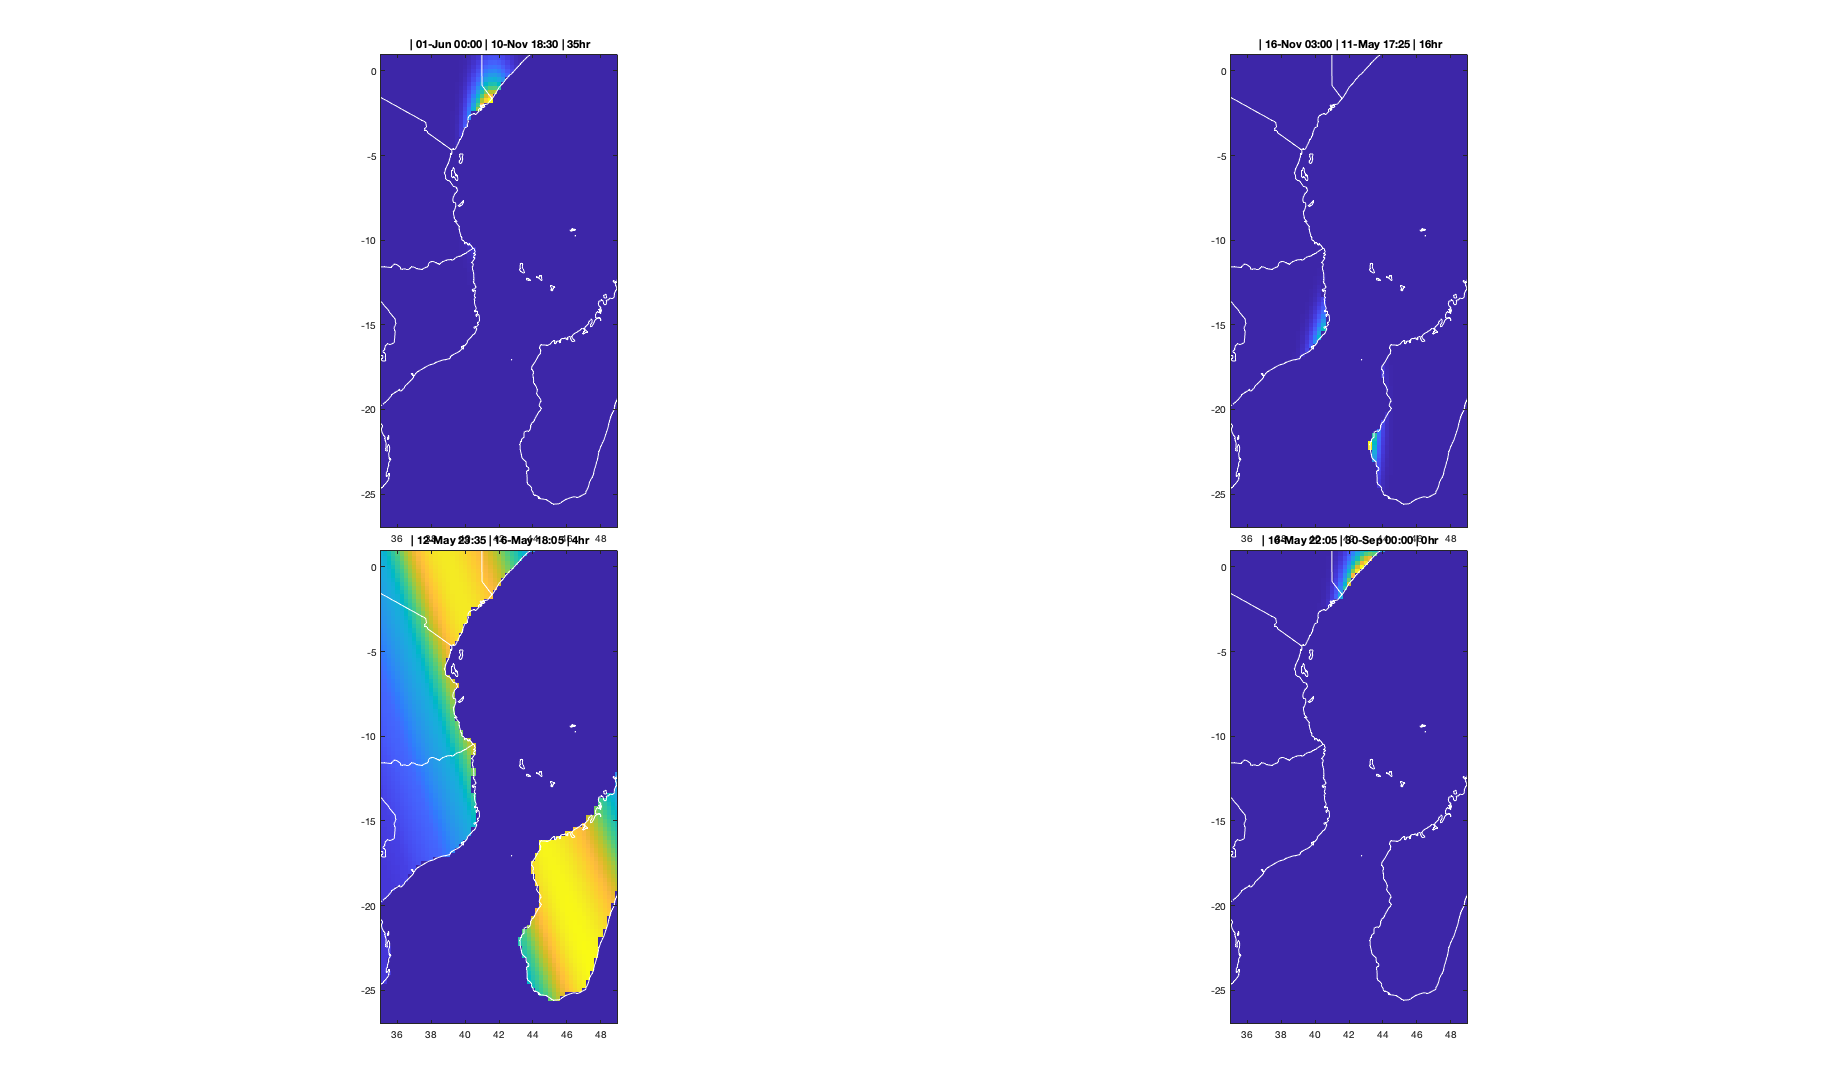

figure('position',[0 0 2400 1400]);
ha=tight_subplot(2,ceil(height(sta_sm)/2));
for i_s = 1:height(sta_sm)
    axes(ha(i_s))
    imagesc(lon_t,lat_t, light_problt(:,:,sta_sm.staID(i_s)));
    hold on;
    plot(rawlt.calib.lat,rawlt.calib.lon,'xr')
    borders('countries','w')

    tt = '';% num2str(sta_sm.staID(i_s));
    tt = tt + " | " + datestr(sta_sm.start(i_s),'dd-mmm HH:MM');
    tt = tt + " | " + datestr(sta_sm.end(i_s),'dd-mmm HH:MM');
    tt = tt + " | "  + num2str(round(hours(sta_sm.actDuration(max(1,i_s))))) + "hr";
    title(tt); set(gca,'ydir','normal')
    axis equal; axis([min(lon_t) max(lon_t) min(lat_t) max(lat_t) ]);
end

## Movement model

Let's assume a range distance that be bird flew from breeding to wintering site.

[~,id]=maxk(stalt.twlNb,2);
dmin = lldistkm([crds_lat(id(1),3) crds_lon(id(1),3)],[crds_lat(id(2),3) crds_lon(id(2),3)])

dmin = 1.7446e+03

Range of possible speed

D=dmin*[1 1.5]; % km

This would lead to an average speed of

AvgSpeed = D*2/sum(hours(stalt.actDuration))

AvgSpeed =    63.8280   95.7421


In m/s

AvgSpeed*1000/60/60

ans =    17.7300   26.5950


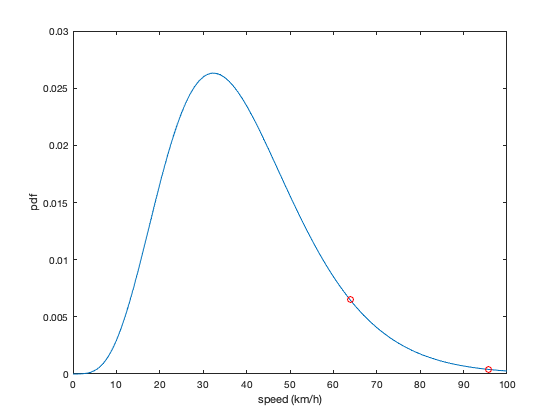

speed_x=0:100;
speed_y = (gampdf(speed_x+1,6,1/0.15));
%speed_y = normpdf(speed_x,mean(AvgSpeed),diff(AvgSpeed)/2);

mvt_pdf = @(x) interp1(speed_x,speed_y,x);
figure; hold on;
plot(speed_x,mvt_pdf(speed_x)); 
plot(AvgSpeed,mvt_pdf(AvgSpeed),'or')
xlabel('speed (km/h)'); ylabel('pdf');

### Load DEM data

see script_ 

load('../data/DEM/MatlabData.mat')

Create grid

lonlt = glon(glon>=tblLog.bndy_W(lt) & glon<=tblLog.bndy_E(lt));
latlt = glat(glat>=tblLog.bndy_S(lt) & glat<=tblLog.bndy_N(lt));

### Pressure

Add pressure outliar

filename = ['Label/activity_label/' rawlt.GDL_ID '_act_pres-labeled.csv'];
if exist(filename)>0
    T2 = readtable(filename);
    % tmp = T2.timestamp(strcmp(T2.series,'pres'));
    % tmp = datetime(cellfun(@(x) [x(1:10) ' ' x(12:16)],tmp,'UniformOutput',false));
    rawlt.pressure.isOutliar = ~isnan(T2.label(strcmp(T2.series,'pres')));
    rawlt.pressure.obsWithOutliars=rawlt.pressure.obs;
    rawlt.pressure.obs(rawlt.pressure.isOutliar)=nan;
end

Surface pressue (https://apps.ecmwf.int/codes/grib/param-db?id=134) available on ERA5 at surface

file='../data/ECMWF/surface_pressure.nc'; %ncdisp(file);
% glon=double(ncread(file,'longitude'));
% glat=flip(double(ncread(file,'latitude')));
spttime = datetime(double(ncread(file,'time'))/24 + datenum('1900-01-01 00:00:00'),'convertFrom','datenum');

Load Pressure data

id_lon = find(glon>=tblLog.bndy_W(lt) & glon<=tblLog.bndy_E(lt));
id_lat = find(glat>=tblLog.bndy_S(lt) & glat<=tblLog.bndy_N(lt));
id_t = find(rawlt.pressure.date(1)<=spttime & spttime <= rawlt.pressure.date(end));
splt = permute(flip(ncread(file,'sp',[id_lon(1) numel(glat)-id_lat(end)+1 1 id_t(1)],[numel(id_lon) id_lat(end)-id_lat(1)+1 1 id_t(end)-id_t(1)+1]),2)/100,[2 1 4 3]);

Calibration location

[~,id_lat_tmp]=min(abs(rawlt.calib.lat-glat(id_lat)));
[~,id_lon_tmp]=min(abs(rawlt.calib.lon-glon(id_lon)));

Compute Pressue error map for each stationary period

pres_rmselt = nan(numel(latlt),numel(lonlt),height(stalt));
pres_problt = nan(numel(latlt),numel(lonlt),height(stalt));
pres_thrlt = false(numel(latlt),numel(lonlt),height(stalt));
pres_n = nan(1,height(stalt));

Allow for some error for the threahodl of pressure

dp_margin = [3 -3];

Loop through each stationary period

for i_s = 1:height(stalt)
    id_tgr = find(stalt.start(i_s)<spttime(id_t) & spttime(id_t) < stalt.end(i_s));
    id_tge = stalt.start(i_s)<rawlt.pressure.date & rawlt.pressure.date < stalt.end(i_s);
    % pres_rmse(:,:,i_s) = sqrt(mean(((  pres(:,:,id_tgr)-reshape(press_movmean(id_tgr),1,1,[])  ).^2),3));

Apply a movinn median to remove outliars and smooth with 1hr

    dt = 1./hours(diff(rawlt.pressure.date(1:2)));

ans = 3×9 table
           start                    end             actNb    actSum    actDuration    twlNb    staID    actEffort      status   
    ____________________    ____________________    _____    ______    ___________    _____    _____    _________    ___________

    01-Jun-2020 00:00:00    10-Nov-2020 18:30:00      1       3630      07:55:00       326       1      08:16:02     "equipment"
    16-Nov-2020 03:00:00    11-May-2021 17:25:00      1       4056      09:05:00       353       7      09:14:15     "wintering"
    16-May-2021 22:05:00    30-Sep-2021 00:00:00      0          0      00:00:00       272      10      00:00:00     "retrieval"


    pres_ge = movmean(movmedian(rawlt.pressure.obs(id_tge),3),dt);

Downscale to same time scale

    id_t_gre = ismember(rawlt.pressure.date(id_tge),spttime(id_t(id_tgr)));
    pres_gr = pres_ge(id_t_gre);

ans = 1×9 table
           start                    end             actNb    actSum    actDuration    twlNb    staID    actEffort              status           
    ____________________    ____________________    _____    ______    ___________    _____    _____    _________    ___________________________

    12-Nov-2020 00:55:00    13-Nov-2020 18:40:00      1       2929      06:20:00        4        3      06:40:14     "migration_post_equipement"


    pres_nlt(i_s)=sum(~isnan(pres_gr));

    if ~isempty(pres_gr)

PART I: Offset / Absolute pressure error

 Perform a second smoothing to remove daily fluctuation (mainly for pressure tide which can trigger the threadhold too easily)

        pres_gr_s = movmean(pres_gr,24,'omitnan');
        pres_gr_s(isnan(pres_gr))=nan;
        splt_s = movmean(splt(:,:,id_tgr),24,3);

Convert the pressure to altitude 

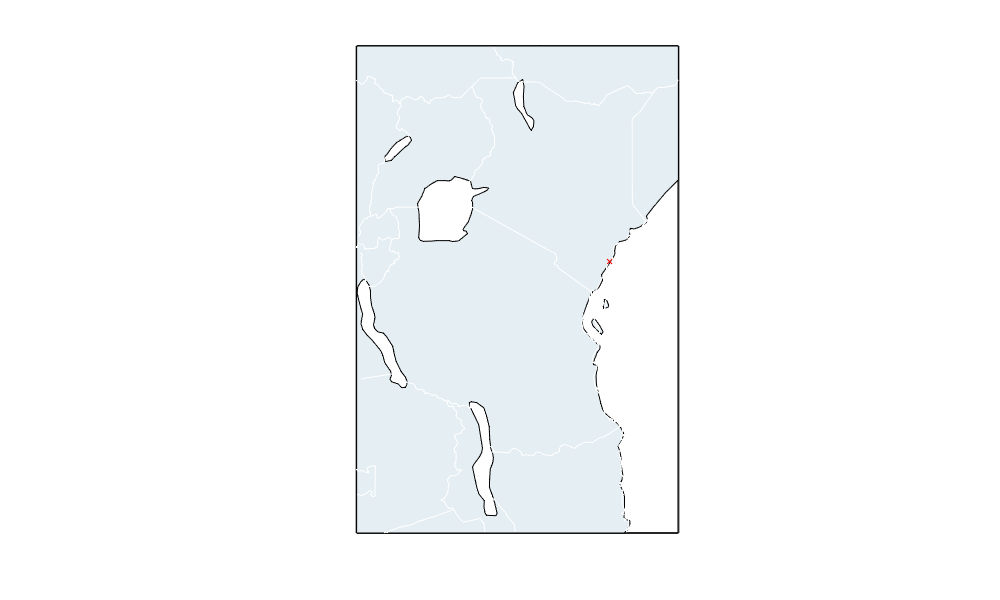

        dh = pressure2altitude(reshape(pres_gr_s,1,1,[]),splt_s);

 use mink and maxk to not be sensitive to outliar

        dh_min = min(dh,[],3,'omitnan');
        dh_max = max(dh,[],3,'omitnan');

Allow for some error for the threahodl of altitude

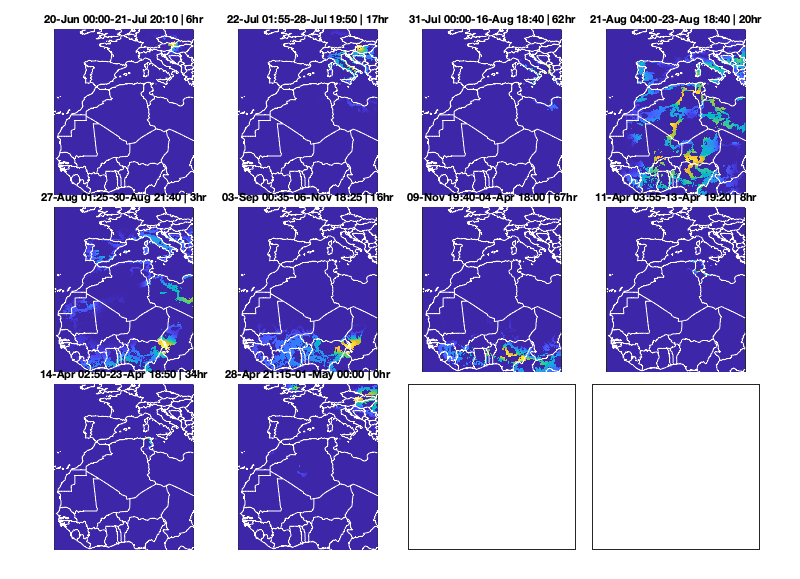

        dh_margin = pressure2altitude(mean(splt_s,3,'omitnan')+reshape(dp_margin,1,1,[]),mean(splt_s,3,'omitnan'));

        pres_thrlt(:,:,i_s) = (dh_min-dh_margin(:,:,1)+geoDEM(id_lat,id_lon))>=DEM_min(id_lat,id_lon) & ...
                (dh_max-dh_margin(:,:,2)+geoDEM(id_lat,id_lon))<=DEM_max(id_lat,id_lon);

        if sum(sum(pres_thrlt(:,:,i_s)))==0
           warning(['no pressure threashold match for this stationary period: ' num2str(i_s) '-' tblLog.GDL_ID{lt}])
        end

 PART II: temporal change

        x = splt(:,:,id_tgr)-mean(splt(:,:,id_tgr),3,'omitnan');
        y = reshape(pres_gr-mean(pres_gr,'omitnan'),1,1,[]);
        e = x-y;

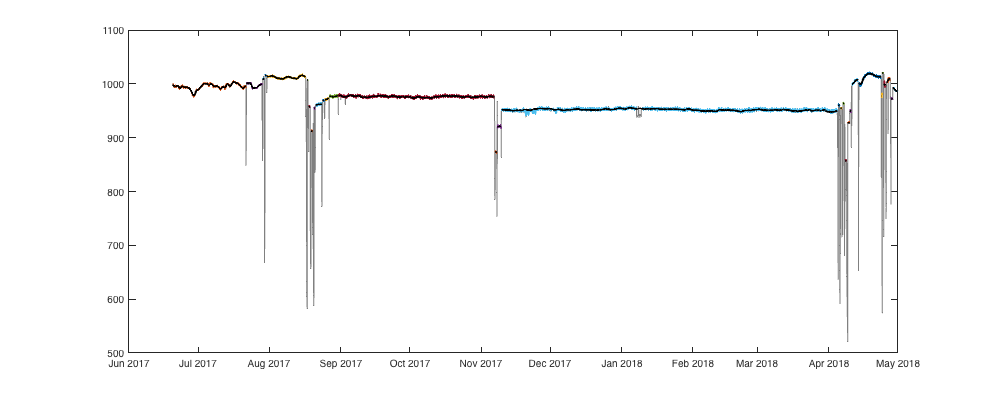

        if strcmp(tblLog.Truncated(lt),'TRUE') && i_s~=0 && i_s~=height(height(stalt)) && min(min(std(e,[],3)))>1
            
            % keyboard
            % TEST to correct for Ring Ouzel data... not workring            
            
%                 x_r=reshape(x,[],size(x,3));
%                 y_r = reshape(y,1,[]);
%                 z = median(x_r(pres_thrlt(:,:,i_s),:),1);
%                 
%                 
%                 
%                 figure; hold on
%                 % plot(reshape(x(id_lat_tmp,id_lon_tmp,:),1,[]))
%                 plot(z); plot(y_r)
%                 
%                 G = [1 cumsum(abs(diff(y_r))>10)+1];
%                 zG=splitapply(@mean,z',G');
%                 yG=splitapply(@mean,y_r',G');
%                 
%                 figure; hold on; plot(z'-zG(G)); plot(y_r'-yG(G));

            
            e(:)=0;
%                 figure; plot(reshape(e(id_lat_tmp,id_lon_tmp,:),1,[]))
%                 i = id_lat_tmp + id_lon_tmp*size(e,1);
%                 figure; plot(e2(i,:))
%                 e2=reshape(e,[],size(e,3));
%                 for i=1:size(e2,1)
%     %                 a=kmeans(e2(i,:)',5);
%     %                 e2(i,a==1) = e2(i,a==1)-mean(e2(i,a==1));
%     %                 e2(i,a==2) = e2(i,a==2)-mean(e2(i,a==2));
%                     thr = graythresh(e2(i,:));
%                     id=thr>e2(i,:);
%                     e2(i,id) = e2(i,id)-mean(e2(i,id),'omitnan');
%                     e2(i,~id) = e2(i,~id)-mean(e2(i,~id),'omitnan');
%                     GMModel = fitgmdist(e2(i,:)',5);
%                     figure; hold on; histogram(e2(i,:),1000); xline(GMModel.mu,'r')
%                 end
%                 e=reshape(e2,size(e));
        end

Assess the match

        et=e(:,:,:);
        if stalt.status(i_s)=="equipment" || stalt.status(i_s)=="retrieval"
            s=tblLog.std_pres_calib(lt);
        else
            s=tblLog.std_pres(lt);
        end
        assert(~isnan(s))

        w = log(pres_n(i_s))-1;
        % pres_rmse{lt}(:,:,i_s) = w .* mean((et/s).^2,3,'omitnan');
        pres_rmselt(:,:,i_s) = w .* mean((et/s).^2,3,'omitnan');

        % RMSE to prob
        pres_problt(:,:,i_s) = exp(-pres_rmselt(:,:,i_s));

        
    else
        % keyboard
        warning(['no pressure available for this stationary period: ' num2str(i_s) '-' tblLog.GDL_ID{lt}])
        pres_problt(:,:,i_s)=0;
        pres_thrlt(:,:,i_s)=true;
    end
end

stalt(stalt.twlNb>10,:)
mh = height(stalt);
i_g=3;
stalt(i_g,:)
figure('position',[0 0 1000 600]); h=worldmap([min(latlt) max(latlt)],[min(lonlt) max(lonlt)]);  hold on;
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(latlt,lonlt,pres_thrlt(:,:,i_g).*pres_problt(:,:,i_g))
bordersm('countries','w');
plotm(rawlt.calib.lat,rawlt.calib.lon,'xr')

### Only long period

grp_id = hours(stalt.end-stalt.start)>48;
sta_sm=stalt(grp_id,:);
sta_sm.actDuration =  splitapply(@sum, stalt.actDuration,cumsum(grp_id));
sta_sm.twlNbStopover =  splitapply(@sum, stalt.twlNb,cumsum(grp_id))-sta_sm.twlNb;

figure('position',[0 0 2400 1400]);
ha = tight_subplot(3,ceil(height(sta_sm)/3));
for i_s = 1:height(sta_sm)
    axes(ha(i_s)); hold on;
    imagesc(lonlt,latlt, pres_thrlt(:,:,sta_sm.staID(i_s)).*pres_problt(:,:,sta_sm.staID(i_s)));

    plot(rawlt.calib.lat,rawlt.calib.lon,'xr')
    borders('countries','w')

    tt = datestr(sta_sm.start(i_s),'dd-mmm HH:MM');
    tt = tt + "-" + datestr(sta_sm.end(i_s),'dd-mmm HH:MM');
    tt = tt + " | "  + num2str(round(hours(sta_sm.actDuration(max(1,i_s)))),2) + "hr";
    title(tt)

    axis equal; axis([min(lonlt) max(lonlt) min(latlt) max(latlt) ]);
end

Best pression match

Downscale to 1hr

dt = 1./hours(diff(rawlt.pressure.date(1:2)));
pres_g = movmedian(rawlt.pressure.obs,3);
pres_g = pres_g(1:dt:end);
gtime = rawlt.pressure.date(1:dt:end);

See on figure

figure('position',[0 0 1000 400]);  hold on
plot(rawlt.pressure.date,rawlt.pressure.obsWithOutliars,'color',[.5 .5 .5])

i_y=nan(height(stalt),1); i_x=i_y;

for i_s = 1:height(stalt)
    id_tgr = stalt.start(i_s) < gtime & gtime < stalt.end(i_s);

    map_prob = pres_thrlt(:,:,i_s).*pres_problt(:,:,i_s);
    [~,id_max] = max(map_prob(:)); [i_y(i_s),i_x(i_s)]=ind2sub(size(map_prob),id_max);

    splt_s_imax = reshape(movmean(splt(i_y(i_s),i_x(i_s),id_tgr),24,3),1,[]);
    
    pres_g_tgr = movmean(pres_g(id_tgr),3);
    plot(gtime(id_tgr), pres_g_tgr,'LineWidth',2)

    plot(gtime(id_tgr),splt_s_imax-nanmean(splt_s_imax)+nanmean(pres_g_tgr),'-k','LineWidth',2)
end